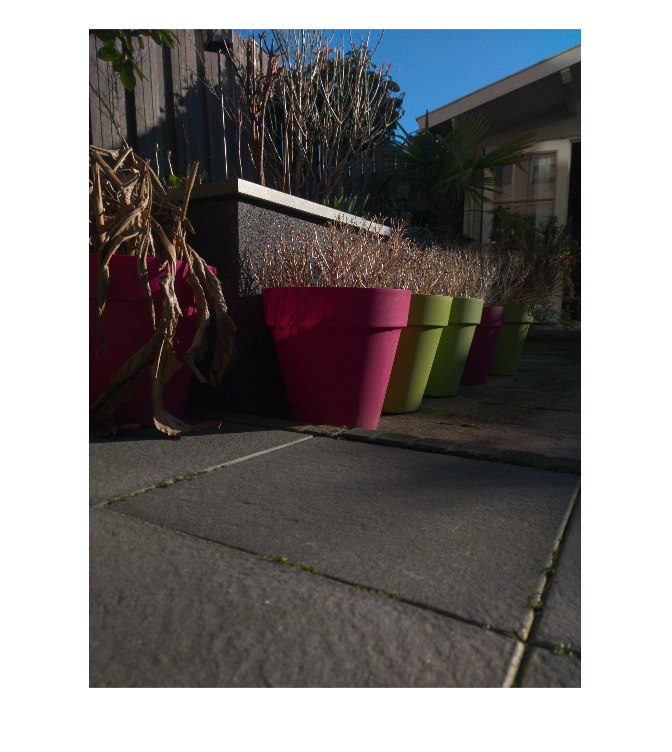

img = single(imread(strcat('cut/potdng0.tif')));
img = rgb2lin(img / 255.0);
imshow(lin2rgb(img));


%imgbil = gather(bilateral(gpuArray(img), 2.0, 0.15));
%imshow(lin2rgb(imgbil));

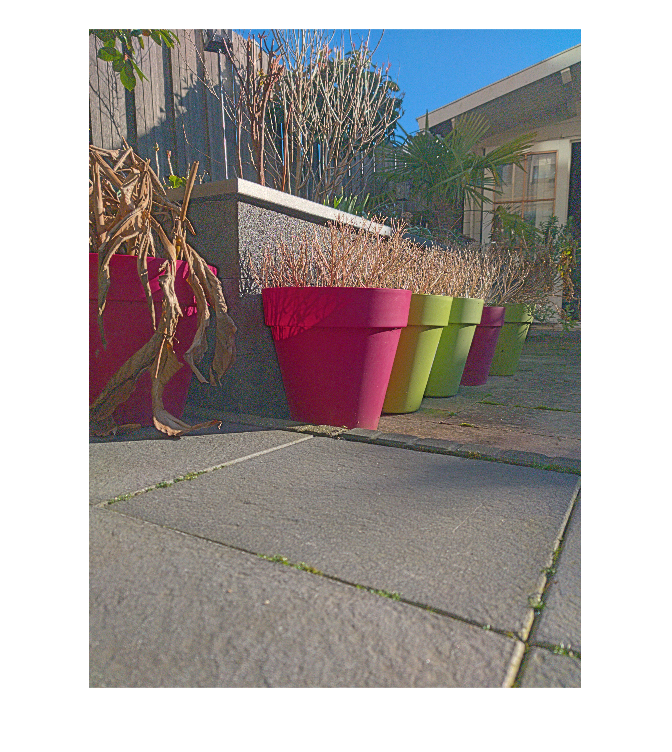

imggpu = gpuArray(img);
imgbil = bilateral(imggpu, 4.0, 0.15);

imghsv = rgb2hsv(imggpu);
imgbilhsv = rgb2hsv(imgbil);

imghsvbase = imgbilhsv(:, :, 3);
imghsvdetail = imghsv(:, :, 3) ./ imghsvbase;

imghsvcombine = imghsv;
imghsvcombine(:, :, 3) = tonemap(imghsvbase, imghsvdetail, 0.45, 1.45);

imshow(lin2rgb(gather(hsv2rgb(imghsvcombine))));